%% MATLAB Fourier Analysis Script (Generates Plots)

% Clear workspace and close figures
clear; close all; clc;

% --- Common Setup ---
T = 2 * pi;       % Period for the square wave (FS)
omega0 = 1;       % Fundamental angular frequency
N_HARMONICS = 50; % For FS reconstruction (Max index for bn_coeffs)

disp('--- 1. Fourier Series: Square Wave Coefficients & Reconstruction ---');

--- 1. Fourier Series: Square Wave Coefficients & Reconstruction ---


disp('Calculating coefficients a0, an, and bn...');

Calculating coefficients a0, an, and bn...



%% 1A. Calculate a0, an, and bn using Numerical Integration (integral)
% Define the square wave function for one period [0, 2*pi]
square_wave_func = @(t) sign(sin(t));

% MATLAB function handles for FS calculation
a0 = (1/T) * integral(square_wave_func, 0, T);
bn_integrand = @(t, n) square_wave_func(t) .* sin(n * omega0 * t);
bn_coeffs = zeros(N_HARMONICS, 1);

for n = 1:N_HARMONICS
    if mod(n, 2) == 1 % Only calculate for odd n (an and a0 are 0)
        bn_integral = integral(@(t) bn_integrand(t, n), 0, T);
        bn = (2/T) * bn_integral;
        bn_coeffs(n) = bn;
    end
end
disp(['a0 (DC Component): ', num2str(a0, 4)]);

a0 (DC Component): 2.209e-17


disp(['b1: ', num2str(bn_coeffs(1), 4), ' (Expected: ', num2str(4/pi, 4), ')']);

b1: 1.273 (Expected: 1.273)


disp('...');

...


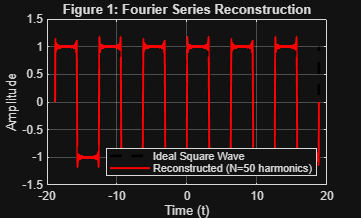



%% 1B. Plot Fourier Series Reconstruction

N_POINTS = 1000;
t_plot = linspace(-3*T, 3*T, N_POINTS);
reconstructed_signal = zeros(size(t_plot));

% --- FIX APPLIED HERE: Loop iterates n = 1, 3, 5, ..., up to N_HARMONICS ---
for n = 1:2:N_HARMONICS 
    if bn_coeffs(n) ~= 0
        % Add the harmonic: bn * sin(n*t)
        reconstructed_signal = reconstructed_signal + bn_coeffs(n) * sin(n * t_plot);
    end
end

% Ideal square wave (requires Signal Processing Toolbox)
ideal_signal = square(t_plot);

figure(1);
plot(t_plot, ideal_signal, 'k--', 'LineWidth', 2, 'DisplayName', 'Ideal Square Wave');
hold on;
plot(t_plot, reconstructed_signal, 'r', 'LineWidth', 1.5, 'DisplayName', ['Reconstructed (N=', num2str(N_HARMONICS), ' harmonics)']);
title('Figure 1: Fourier Series Reconstruction');
xlabel('Time (t)');
ylabel('Amplitude');
ylim([-1.5 1.5]);
legend('Location', 'southeast');
grid on;



%% ---------------------------------------------------------------------

disp(' ');

disp('--- 2. Fourier Transform (FT): Decaying Exponential ---');

--- 2. Fourier Transform (FT): Decaying Exponential ---



%% 2. FT: Decaying Exponential Approximation

a = 1;
dt = 0.01;
T_max = 100;
t_ft = 0:dt:T_max;
x_t_ft = exp(-a * t_ft); % Signal: e^(-a*t)*u(t)

% Built-in FFT (Approximation of FT)
Fs = 1/dt;
N_ft = length(x_t_ft);
X_ft = fft(x_t_ft);
freqs_fft = (0:N_ft-1) * Fs / N_ft;

% Analytical Solution: Magnitude |X(f)| = 1 / sqrt(a^2 + (2*pi*f)^2)